Open it as live script!!!

Load data.

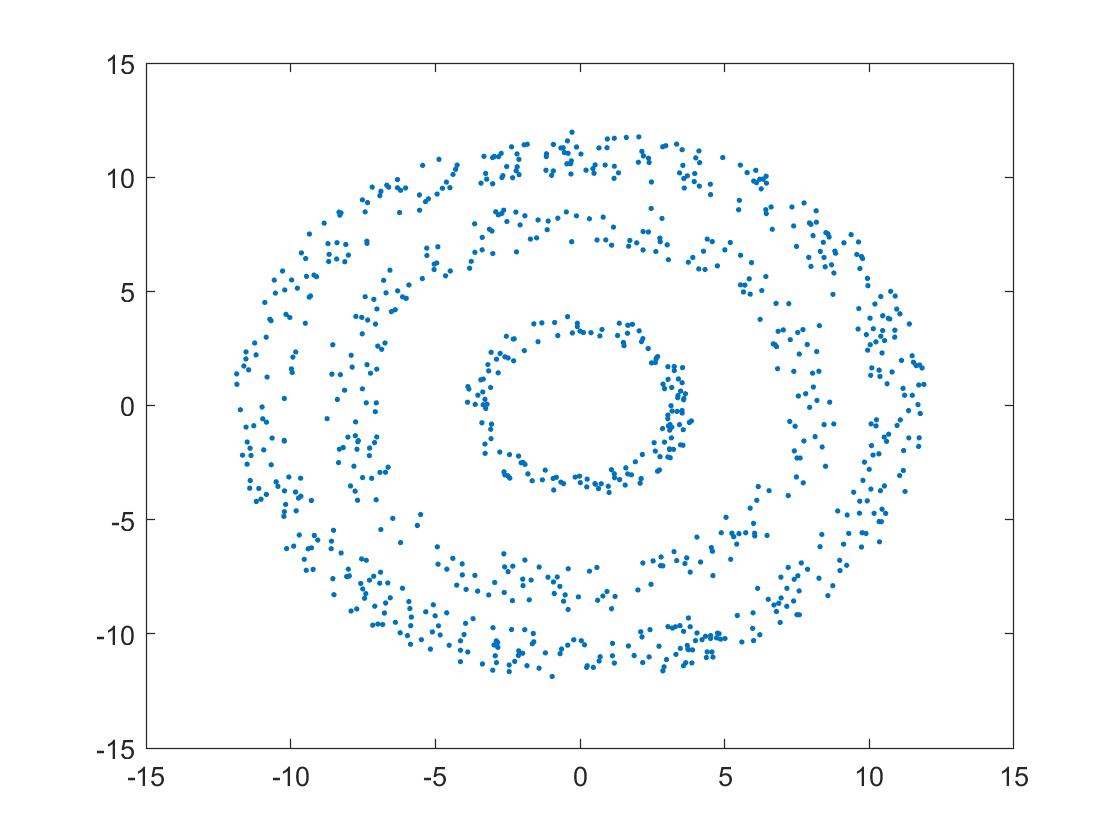

load('Data\cluster_data.mat');
X = cluster_data;
plot(X(:,1),X(:,2),'.');

k is the number of clusters.

k = 3;
y = SpectralClustering(X,k);

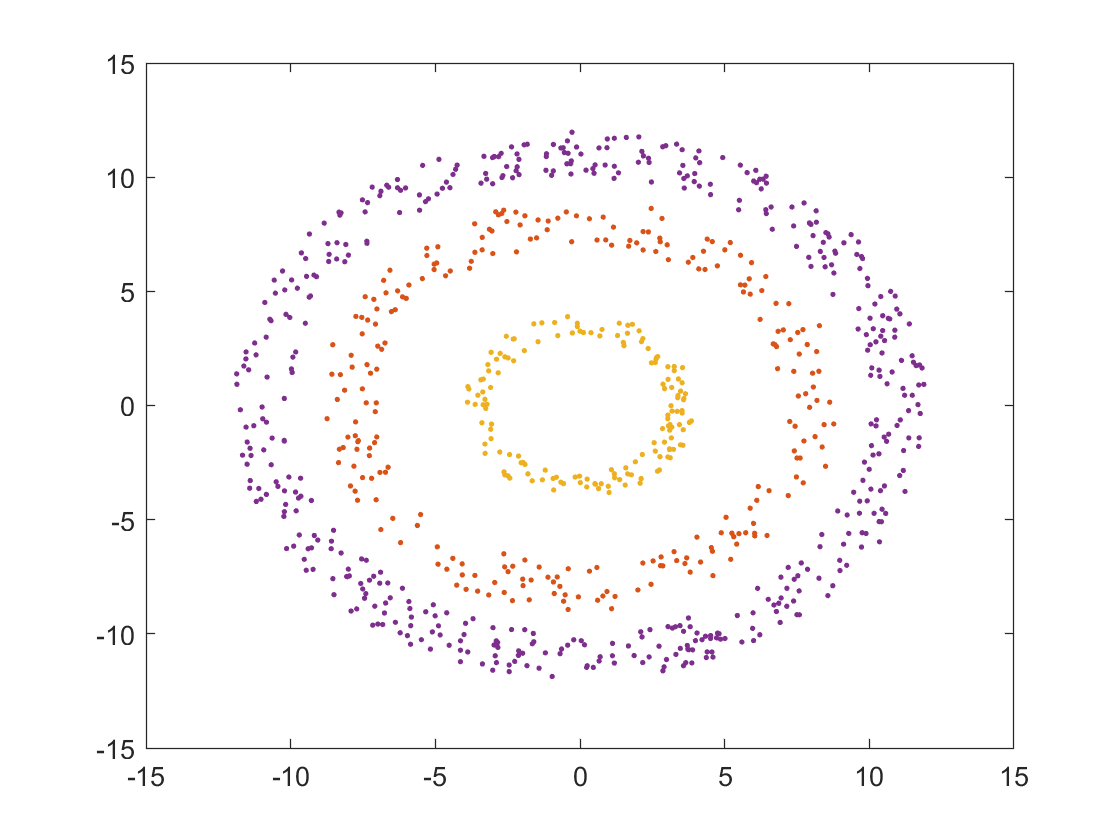

z = [X,y];
c = cell(k,1);
for i = 1:k
    c{i} = z(z(:,3)==i,1:2);
    hold on;
    plot(c{i}(:,1),c{i}(:,2),'.');
end